scenario = radarScenario;
tower = platform(scenario);
tower.ClassID = 3;
%tower.Signatures{1};
load('RCSCylinderExampleData.mat','cylinder');

tower.Signatures{1} = rcsSignature('Pattern', cylinder.RCSdBsm, ...
    'Azimuth', cylinder.Azimuth, 'Elevation', cylinder.Elevation, ...
    'Frequency', cylinder.Frequency);
tower.Dimensions = struct( ...
    'Length', 10, ...
    'Width', 10, ...
    'Height', 60, ...
    'OriginOffset', [0 0 30]);
scenario.platformPoses

ans = struct with fields:
         PlatformID: 1
            ClassID: 3
           Position: [0 0 0]
           Velocity: [0 0 0]
       Acceleration: [0 0 0]
        Orientation: [1×1 quaternion]
    AngularVelocity: [0 0 0]


tower.Trajectory

ans =   kinematicTrajectory with properties:

               SampleRate: 100
                 Position: [0 0 0]
              Orientation: [1×1 quaternion]
                 Velocity: [0 0 0]
       AccelerationSource: 'Input'
    AngularVelocitySource: 'Input'


tYaw = 0;
tPitch = 4;
tRoll = 0;
tower.Trajectory.Orientation = quaternion([tYaw tPitch tRoll],'eulerd','zyx','frame');
tPlot = theaterPlot('XLim',[-50 50],'YLim',[-50 50],'ZLim',[-100 0]);
pPlotter = platformPlotter(tPlot,'DisplayName','tower');

pose = platformPoses(scenario);
towerPose = pose(1);
towerDims = tower.Dimensions;

plotPlatform(pPlotter, towerPose.Position, towerDims, towerPose.Orientation);
set(tPlot.Parent,'YDir','reverse', 'ZDir','reverse');
view(tPlot.Parent, -37.5, 30)
towerRadar = radarDataGenerator('SensorIndex', 1, ...
    'UpdateRate', 10, ...
    'MountingLocation', [0 0 -60], ...
    'ScanMode', 'No scanning', ...
    'HasINS', true, ...
    'TargetReportFormat', 'Detections', ...
    'DetectionCoordinates', 'Scenario');

tower.Sensors = towerRadar;
tPlot.XLimits = [-5000 5000];
tPlot.YLimits = [-5000 5000];
tPlot.ZLimits = [-1000 0];

covPlotter = coveragePlotter(tPlot,'DisplayName','Sensor Coverage');
plotCoverage(covPlotter, coverageConfig(scenario));
helicopter = platform(scenario);
helicopter.Dimensions = struct( ...
    'Length',30, ...
    'Width', .1, ...
    'Height', 7, ...
    'OriginOffset',[0 8 -3.2]);

helicopter.Signatures = rcsSignature( ...
    'Pattern',[40 40; 40 40], ...
    'Elevation',[-90; 90], ...
    'Azimuth',[-180,180]);
    



%Platform Motion and Animation
helicopter.Trajectory = waypointTrajectory([2000 500 -250; 2000 -500 -250],[0 25]);
profiles = platformProfiles(scenario);
dimensions = vertcat(profiles.Dimensions);

while advance(scenario)
    poses = platformPoses(scenario);
    positions = vertcat(poses.Position);
    orientations = vertcat(poses.Orientation);
    plotPlatform(pPlotter, positions, dimensions, orientations);
    plotCoverage(covPlotter, coverageConfig(scenario));
    % to animate more slowly uncomment the following line
    %pause(0.01)
    % Print the position and orientation of the helicopter 
    fprintf('Helicopter Position: [%f, %f, %f]\n', helicopter.Position(1), helicopter.Position(2), helicopter.Position(3)); 
    
end

Helicopter Position: [2000.000000, 500.000000, -250.000000]
Helicopter Position: [2000.000000, 496.000000, -250.000000]
Helicopter Position: [2000.000000, 492.000000, -250.000000]
Helicopter Position: [2000.000000, 488.000000, -250.000000]
Helicopter Position: [2000.000000, 484.000000, -250.000000]
Helicopter Position: [2000.000000, 480.000000, -250.000000]
Helicopter Position: [2000.000000, 476.000000, -250.000000]
Helicopter Position: [2000.000000, 472.000000, -250.000000]
Helicopter Position: [2000.000000, 468.000000, -250.000000]
Helicopter Position: [2000.000000, 464.000000, -250.000000]
Helicopter Position: [2000.000000, 460.000000, -250.000000]
Helicopter Position: [2000.000000, 456.000000, -250.000000]
Helicopter Position: [2000.000000, 452.000000, -250.000000]
Helicopter Position: [2000.000000, 448.000000, -250.000000]
Helicopter Position: [2000.000000, 444.000000, -250.000000]
Helicopter Position: [2000.000000, 440.000000, -250.000000]
Helicopter Position: [2000.000000, 436.0

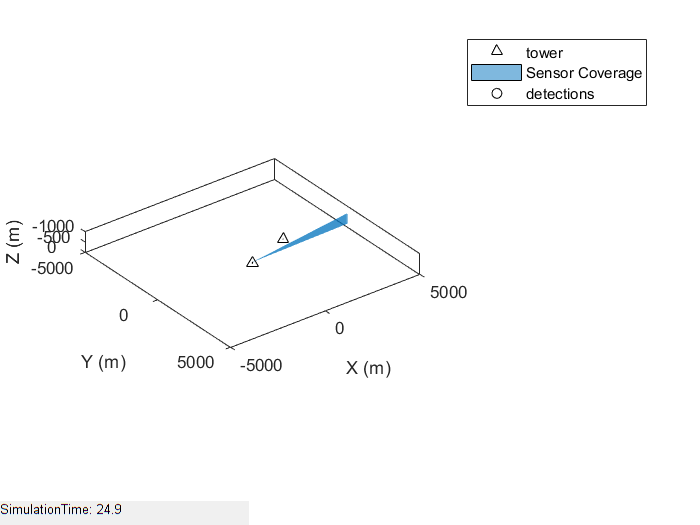

No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No det

Detection Position: [1993.451185, 19.130032, -199.542200]
Detection Position: [1992.583788, 15.305078, -199.481546]
Detection Position: [1999.784551, 12.977790, -199.985072]
Detection Position: [1996.819295, 3.679755, -199.777721]
Detection Position: [1989.368706, -1.177505, -199.256725]
Detection Position: [1994.718955, 3.488374, -199.630851]
Detection Position: [1993.006832, 3.400633, -199.511128]
Detection Position: [1999.763458, 3.553987, -199.983597]
Detection Position: [2004.173876, -0.357629, -200.292004]
Detection Position: [2005.720956, -3.523607, -200.400186]
Detection Position: [1998.557754, 11.940263, -199.899286]
Detection Position: [2005.130480, -2.276045, -200.358896]
Detection Position: [1993.504631, -0.798058, -199.545937]
Detection Position: [1994.419574, -9.117018, -199.609916]
Detection Position: [1998.162138, -7.841601, -199.871622]
Detection Position: [1996.499177, -5.153310, -199.755336]
Detection Position: [2001.029663, -19.933573, -200.072139]


No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No detections
No det




scenario.UpdateRate = 0;
fig = ancestor(tPlot.Parent,'Figure');
timeReadout = uicontrol(fig,'Style','text','HorizontalAlignment','left','Position',[0 0 200 20]);
timeReadout.String = "SimulationTime: " + scenario.SimulationTime;
dPlotter = detectionPlotter(tPlot,'DisplayName','detections');


restart(scenario);

while advance(scenario)
    timeReadout.String = "SimulationTime: " + scenario.SimulationTime;
    detections = detect(scenario);
    
    % extract column vector of measurement positions
    allDetections = [detections{:}];
    if ~isempty(allDetections)
        measurement = cat(2,allDetections.Measurement)';
            
        fprintf('Detection Position: [%f, %f, %f]\n', allDetections.Measurement(:));
               
        % call Python script with laser interaction
        %system(['python plot_detection.py ' num2str(measurement)]);
    else
        measurement = zeros(0,3);
        fprintf('No detections\n');
        

    end
    % Plot the detections
    plotDetection(dPlotter, measurement);
    % Plot the platforms and coverage
    poses = platformPoses(scenario);
    positions = vertcat(poses.Position);
    orientations = vertcat(poses.Orientation);
    plotPlatform(pPlotter, positions, dimensions, orientations);
    plotCoverage(covPlotter, coverageConfig(scenario));
      
end